dataFolder = "/Users/amkhrjee/Developer/BB709/LinearAlgebra/data"; % Change this
I1 = double(imread(fullfile(dataFolder, 'ct','slice_038.png')))/255;
I2 = double(imread(fullfile(dataFolder, 'ct','slice_039.png')))/255;

disp("First Image:")

First Image:


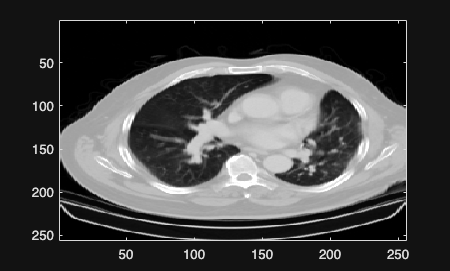

imagesc(I1)
colormap gray

disp("Second Image:")

Second Image:


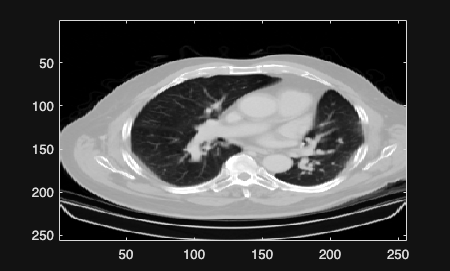

imagesc(I2)
colormap gray

disp("Avegrage Image:")

Avegrage Image:


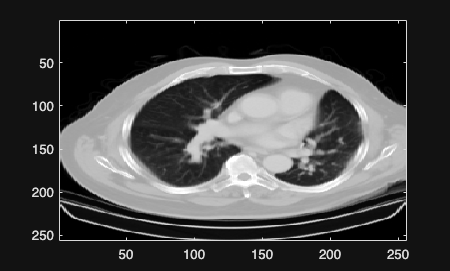

averageImage = (I1 + I2)/2;
imagesc(averageImage)
colormap gray

disp("Difference Image:")

Difference Image:


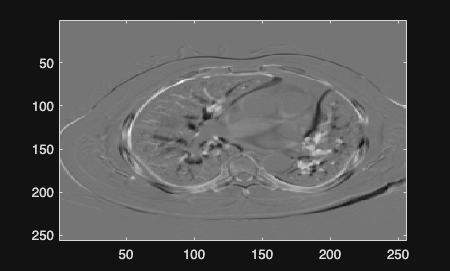

diffImage = I2 - I1;
imagesc(diffImage)
colormap gray

We can get the Frobenius norm of the `diffImage` matrix.

Learn more here: https://mathworld.wolfram.com/FrobeniusNorm.html

distance = norm(diffImage,'fro')

distance = 17.9709

x1 = I1(:);
x2 = I2(:);
cosineValue = dot(x1,x2)/(norm(x1)*norm(x2));
angleDegrees = acosd(cosineValue)

angleDegrees = 8.1520